data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



Wi1=((s/(16*pi))+0.3)/((s/(64*pi))+1)

Wi1 =
 
    201.1 s + 3032
  ------------------
  50.27 s + 1.011e04
 
Continuous-time transfer function.



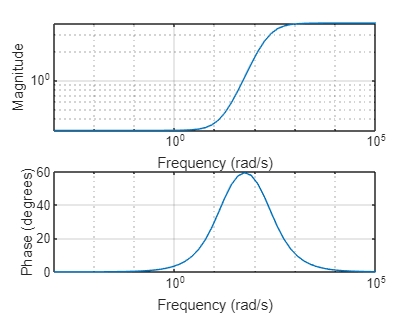

Wi2=((s/(16*pi))+0.3)/((s/(64*pi))+1);
Wi=[Wi1 0;0 Wi2];

Wo1=((0.05*s)+0.02)/((0.01*s)+1);
Wo2=((0.05*s)+0.02)/((0.01*s)+1);
Wo=[Wo1 0;0 Wo2];



Wia = [1/(64*pi) 1];
Wib = [1/(16*pi) 0.3];
wi = logspace(-3,5);

figure
freqs(Wib,Wia,wi)

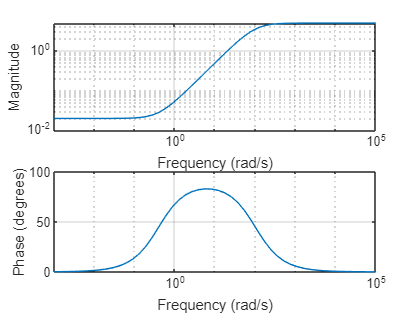



Woa = [0.01 1];
Wob = [0.05 0.02];
wo = logspace(-3,5);

figure
freqs(Wob,Woa,wo)


H = ultidyn("H",2)

H =   Uncertain LTI dynamics "H" with 2 outputs, 2 inputs, and gain less than 1.



DeltaInput=Wo*H*Wi

DeltaInput =

  Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    H: Uncertain 2x2 LTI, peak gain = 1, 1 occurrences

Type "DeltaInput.NominalValue" to see the nominal value, "get(DeltaInput)" to see all properties, and "DeltaInput.Uncertainty" to interact with the uncertain elements.



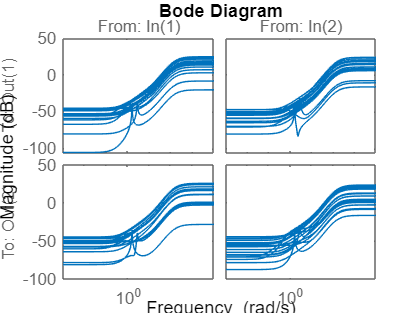

figure()
bodemag(DeltaInput)

S = svd(DeltaInput.A)

S =   201.0619
  201.0619
  100.0000
  100.0000


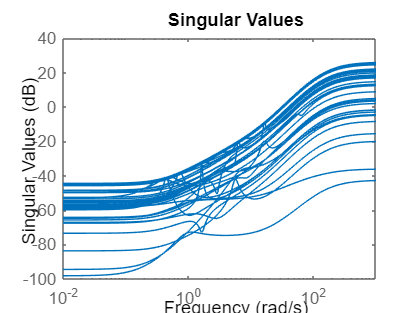

figure()
sigma(DeltaInput)

wB1=0.3*2*pi; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/10000; % desired disturbance attenuation inside bandwidth
M=3; % desired bound on hinfnorm(S)
Wp11=tf([1/M wB1],[1 wB1*A]);
Wp=[Wp11 0; 0 wB2]; %

% Control weights
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[]; % Empty weight

G=tf(FWT(1:2,1:2));

%get controller from first part
Plant=augw(G,Wp,Wu,[]); 
P1=minreal(Plant) 

5 states removed.

P1 =
 
  A = 
              x1         x2         x3         x4         x5         x6         x7         x8
   x1     0.2131    -0.0295    0.03336       -1.3     0.4763     0.1823    0.02628    0.05079
   x2     0.4143   -0.02882   -0.00703     0.2492    -0.4512  -0.008475   -0.03462   -0.02736
   x3     0.1295     0.2552    0.03197    -0.1315     0.2071    0.06565    0.06406    0.02923
   x4     0.7125    -0.1849     0.2443     0.1779      -3.35     -1.207    -0.3706    -0.3839
   x5     -1.216    -0.1159    -0.3458      2.574    -0.6483    -0.5263   -0.05786     -0.166
   x6    -0.3994   -0.05239   -0.07982     0.6352    -0.2924    -0.2267   -0.03432   -0.06571
   x7    0.09169   -0.03565   0.009626     0.2942    -0.1525   0.008626   -0.01609  -0.002359
   x8    -0.5212    0.02677    -0.1553     0.2231    -0.2404    -0.3302   -0.02251    -0.1025
 
  B = 
                ?           ?  Beta (deg)  tau_e (Nm)
   x1    -0.05644           0    -0.05566     0.01069
   x

[K,CL,GAM,INFO] = hinfsyn(P1,2,2); %K is controller

P=[zeros(2) zeros(2) zeros(2) Wi;Wo*G zeros(2) zeros(2) Wo*G;Wp*G Wp Wp Wp*G;zeros(2) zeros(2) zeros(2) Wu; -G -1*eye(2) -1*eye(2) -G]

P =
 
  From input "Beta (deg)" to output...
   1:  0
 
   2:  0
 
       -0.003994 s^5 - 0.001763 s^4 - 0.04345 s^3 - 0.01703 s^2 - 0.001599 s - 0.0006916
   3:  ---------------------------------------------------------------------------------
         0.01 s^6 + 1.006 s^5 + 0.7077 s^4 + 11.02 s^3 + 4.715 s^2 + 0.5439 s + 0.1827
 
            -0.002437 s^4 - 0.002715 s^3 - 0.004445 s^2 - 0.004099 s - 0.00104
   4:  -----------------------------------------------------------------------------
       0.01 s^6 + 1.006 s^5 + 0.7077 s^4 + 11.02 s^3 + 4.715 s^2 + 0.5439 s + 0.1827
 
       -0.02663 s^5 - 0.1517 s^4 - 0.2955 s^3 - 1.633 s^2 + 0.0007121 s - 0.06518
   5:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
            -0.009748 s^3 - 0.006961 s^2 - 0.01499 s - 0.0104
   6:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3

P=minreal(P)

P =
 
  From input "Beta (deg)" to output...
   1:  0
 
   2:  0
 
       -0.3994 s^5 - 0.1763 s^4 - 4.345 s^3 - 1.703 s^2 - 0.1599 s - 0.06916
   3:  ---------------------------------------------------------------------
       s^6 + 100.6 s^5 + 70.77 s^4 + 1102 s^3 + 471.5 s^2 + 54.39 s + 18.27
 
             -0.2437 s^4 - 0.2715 s^3 - 0.4445 s^2 - 0.4099 s - 0.104
   4:  --------------------------------------------------------------------
       s^6 + 100.6 s^5 + 70.77 s^4 + 1102 s^3 + 471.5 s^2 + 54.39 s + 18.27
 
       -0.02663 s^5 - 0.1517 s^4 - 0.2955 s^3 - 1.633 s^2 + 0.0007121 s - 0.06518
   5:  ---------------------------------------------------------------------------
       s^6 + 0.5981 s^5 + 10.98 s^4 + 4.711 s^3 + 0.543 s^2 + 0.1828 s + 3.444e-05
 
            -0.009748 s^3 - 0.006961 s^2 - 0.01499 s - 0.0104
   6:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
   7:  0
 
   8:  0
 
     

Pl=ss(P)

Pl =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1       -201.1           0           0           0           0           0           0           0
   x2            0      -201.1           0           0           0           0           0           0
   x3            0           0           0           0           0           0           0     -0.2855
   x4            0           0         0.5           0           0           0           0     -0.4249
   x5            0           0           0         0.5           0           0           0      -1.842
   x6            0           0           0           0           2           0           0      -8.612
   x7            0           0           0           0           0          16           0      -8.846
   x8            0           0           0           0           0           0           8      -100.6
   x9            0           0           0           0     

Pss=minreal(Pl)

45 states removed.

Pss =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1       -50.22       50.39       2.761     -0.7333       1.039       7.087    -0.02808      0.1143
   x2        50.71      -53.47     0.05816     -0.4859      0.7534     -0.1204    0.001226     0.09281
   x3       0.3844      -2.453     -0.2251      0.4355     -0.2311     -0.7687    0.005398       0.285
   x4      -0.7983      0.1444     -0.0112     -0.1629    -0.03668       1.727    -0.01278     -0.7227
   x5       0.4161    -0.08781    -0.05166      0.3936     -0.2933     -0.8355    0.004603      0.1702
   x6         5.91      -1.237      -0.734       1.929       -1.22      -12.52     -0.7712   -0.002611
   x7     -0.02417    0.005059    0.003002   -0.007889    0.004831     -0.7712      -201.1      0.7991
   x8    0.0005684   0.0001048  -7.894e-05   0.0001536  -5.944e-05   -0.001264      0.7991        -100
   x9        19.35      -1.677      -2

N=lft(P,K)

N =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1       -201.1           0           0           0           0           0           0           0
   x2            0      -201.1           0           0           0           0           0           0
   x3            0           0           0           0           0           0           0     -0.2855
   x4            0           0         0.5           0           0           0           0     -0.4249
   x5            0           0           0         0.5           0           0           0      -1.842
   x6            0           0           0           0           2           0           0      -8.612
   x7            0           0           0           0           0          16           0      -8.846
   x8            0           0           0           0           0           0           8      -100.6
   x9            0           0           0           0      

N=minreal(N)

46 states removed.

N =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8
   x1        73.82       216.5      -381.3       851.9      -986.5       -2698        -207   1.147e+04
   x2        35.25       17.53      -187.7         306      -348.6      -964.7      -70.79        4104
   x3       -41.35      -156.1       152.5      -420.6       479.8        1339       97.66       -5671
   x4       -6.382      -15.76       31.29      -68.61       78.13       217.9       15.86      -924.7
   x5        245.5         642       -1151        2523       -2872       -8001      -581.3   3.394e+04
   x6       -79.54      -206.5       377.1      -822.8         936        2607       189.6  -1.106e+04
   x7        145.1       379.6      -679.9        1491       -1697       -4727      -343.3   2.005e+04
   x8       0.7249       1.879      -3.447       7.512      -8.573      -23.81      -1.688       100.6
   x9       0.1021      0.2672     -0.47

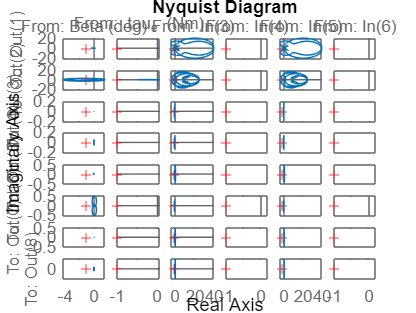

nyquist(N)